# 6. Image Regression

load imageRegressionData.mat

## What is Regression?

Regression is another task that can be accomplished with deep learning. *Regression* refers to assigning continuous response values to data, instead of discrete classes.

One example of image regression is correcting rotated images. The input data is a rotated image, and the known response is the angle of rotation.

회귀는 딥러닝으로 수행할 수 있는 또 다른 작업입니다. 회귀는 개별 클래스 대신 데이터에 연속 응답 값을 할당하는 것을 의미합니다.

이미지 회귀의 한 가지 예는 회전된 이미지를 수정하는 것입니다. 입력 데이터는 회전된 이미지이고 알려진 응답은 회전 각도입니다.

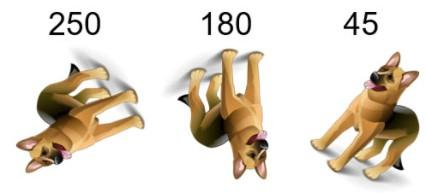

You will build a network that corrects the color in images.

A set of images have been modified by changing their red, green, and blue channels. The response for each modified image is three numeric values that correspond to the intensity increase or decrease of the corresponding channel.

이미지의 색상을 수정하는 네트워크를 구축합니다.

빨간색, 녹색 및 파란색 채널을 변경하여 이미지 세트가 수정되었습니다. 수정된 각 이미지에 대한 응답은 해당 채널의 강도 증가 또는 감소에 해당하는 세 개의 숫자 값입니다.

### Peek into the data

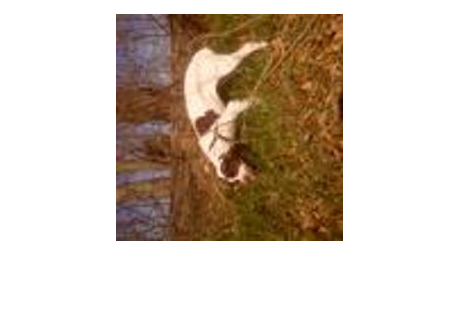

trainingData;
imshow(imread(trainingData.File{1}))

size(imread(trainingData.File{1}))

ans =    227   227     3


## Transfer Learning for Image Regression

###     Modify the network layers for regression

- Replace the `fullyConnectedLayer` 

- Delete the softmax layer and the classification layer

- Add a `regressionLayer`

net = alexnet

net =   SeriesNetwork - 속성 있음:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


layers = net.Layers

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU                  ReLU
     4   'norm1'    교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU                  ReLU
     8   'norm2'    교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU                  ReLU
    12   'conv4'    2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13 

%analyzeNetwork(net)

###     Prepare the data

trainds = augmentedImageDatastore([227,227],trainingData)

trainds =   augmentedImageDatastore - 속성 있음:

         NumObservations: 2040
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [227 227]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


testds = augmentedImageDatastore([227,227],testData)

testds =   augmentedImageDatastore - 속성 있음:

         NumObservations: 20
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'none'
              OutputSize: [227 227]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


layers(end-2) = fullyConnectedLayer(3);
layers(end-1:end) = [];
layers = [layers; regressionLayer]

layers =   다음 계층을 포함한 24×1 Layer 배열:

     1   'data'    영상 입력               227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   2차원 컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU                  ReLU
     4   'norm1'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   2차원 그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU                  ReLU
     8   'norm2'   교차 채널 정규화         교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   2차원 최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   2차원 컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU                  ReLU
    12   'conv4'   2차원 그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'   

## Train the Network 

options = trainingOptions("adam","InitialLearnRate",0.0001,... %전이학습이기 때문에, 초기학습률을 작게해도 됨. (오히려 효율적?)
    "MaxEpochs",30,"Plots","training-progress")

options =   TrainingOptionsADAM - 속성 있음:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'

newNet = trainNetwork(trainds, layers, options) %회귀에서 ColorPreprocessing X

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：１０　｜　　　　　　　　４１．９５　｜　　　　　　８８０．０　｜　１．００００ｅ－０４　｜
｜　　　　　　　４　｜　　　　　　５０　｜　　　　　００：０４：３０　｜　　　　　　　　１１．６３　｜　　　　　　　６７．７　｜　１．００００ｅ－０４　｜
｜　　　　　　　７　｜　　　　　　９６　｜　　　　　００：０８：２９　｜　　　　　　　　　７．７０　｜　　　　　　　２９．７　｜　１．００００ｅ－０４　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
훈련 완료: 수동으로 중지되었습니다.


newNet =   SeriesNetwork - 속성 있음:

         Layers: [24×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'regressionoutput'}


## Evaluate the Network

Predict the response for all images in the test data and calculate the root mean squre error (RMSE) for the test data set.

테스트 데이터의 모든 이미지에 대한 응답을 예측하고 테스트 데이터 세트에 대한 RMSE(평균 평방 오차)를 계산합니다.

testPred = predict(newNet,testds)

testPred = 20×3 single 행렬
   -5.1089  -22.2224  -14.9388
  -15.4492   31.2337    5.1922
  -25.4382  -13.3202   23.2118
   -3.1752   12.4321   -9.7846
  -55.0662   31.3663    8.7128
    3.4822  -37.3931   33.6288
   -0.1719    9.2864  -13.5510
   38.3757  -41.7559   16.8135
   11.7689   21.2198  -14.5367
  -32.4017   26.5395  -24.7912


rgbGT = testData.Color

rgbGT =      8   -13   -14
    -1    43     5
   -15   -11    24
     7    21   -11
   -51    28     6
     4   -42    28
     0    10   -22
    49   -22    20
    19    28   -19
   -21    47   -23


err = rgbGT - testPred

err = 20×3 single 행렬
   13.1089    9.2224    0.9388
   14.4492   11.7663   -0.1922
   10.4382    2.3202    0.7882
   10.1752    8.5679   -1.2154
    4.0662   -3.3663   -2.7128
    0.5178   -4.6069   -5.6288
    0.1719    0.7136   -8.4490
   10.6243   19.7559    3.1865
    7.2311    6.7802   -4.4633
   11.4017   20.4605    1.7912


rmse = sqrt(mean(err.^2))

rmse = 1×3 single 행 벡터
    8.5541    8.5428    4.6230


## Correct the color

Use the network to correct the rgb value of the first test image and display the corrected image.

네트워크를 사용하여 첫 번째 테스트 이미지의 rgb 값을 수정하고 수정된 이미지를 표시합니다.

imageNum = 10

imageNum = 10

testImage = imread(testData.File{imageNum})

testImage = 227×227×3 uint8 배열
testImage(:,:,1) =

   177   156   142   163   173   169   178   165   158   142   150   153   158   154   135   138   149   153   152   147   143   147   156   162   157   154   156   139   143   161   148   139   153   187   127   102   146   133   121   161   163   117    52    22    37    52    77   115   140   164   141   113   132   126    67    18    21    23    51   140   195   179   175   187   169   167   152   144   166   175   155   131   106   135   170   139   140   137   140   125   124   140   146   142   142   150   152   145   129   118   126   136   134   144   144   123   117   114   126   125   109   121   115    69    57    40    50    67    79   125   158   147   149   145   131   135   116    85    96   109   119   116   133   138   116   111   125   127   121   157   181   171   159   159   155   144   133   126   138   164   174   163   161   173   163   168   162   161   151   148   162   147   159   152   142   132   142   163 

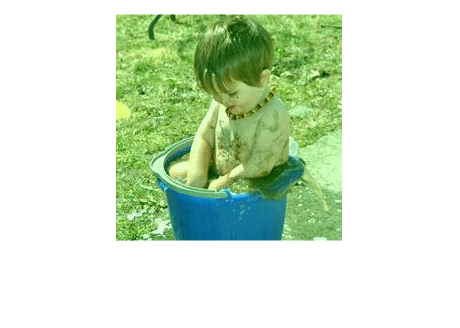

imshow(testImage)

rgb = testpred(imageNum,:)

rgb = 1×3 single 행 벡터
  -20.9861   23.0332  -11.0354


% imshow(rgb)
correctedImage = correctColor(testImage, rgb)

correctedImage = 227×227×3 uint8 배열
correctedImage(:,:,1) =

   198   177   163   184   194   190   199   186   179   163   171   174   179   175   156   159   170   174   173   168   164   168   177   183   178   175   177   160   164   182   169   160   174   208   148   123   167   154   142   182   184   138    73    43    58    73    98   136   161   185   162   134   153   147    88    39    42    44    72   161   216   200   196   208   190   188   173   165   187   196   176   152   127   156   191   160   161   158   161   146   145   161   167   163   163   171   173   166   150   139   147   157   155   165   165   144   138   135   147   146   130   142   136    90    78    61    71    88   100   146   179   168   170   166   152   156   137   106   117   130   140   137   154   159   137   132   146   148   142   178   202   192   180   180   176   165   154   147   159   185   195   184   182   194   184   189   183   182   172   169   183   168   180   173   163   153   

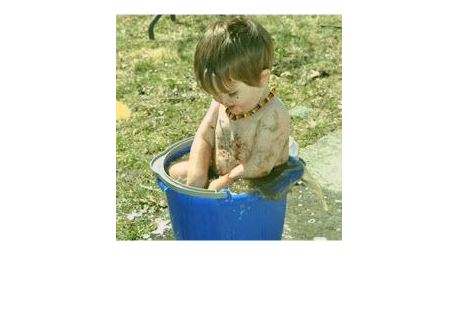

% correctColor 함수 보기(주어짐!)
imshow(correctedImage)

% +1 0 -1
% 정답값은 0. 평균 냈더니 0이 나온것 완벽하다. 그래서 에러값에 대한 제곱을 하고 평균 값을 구한다. 거리에 대한 정보만 있고
% +,- 와 같은 방향 값은 사라진다. rmse.